# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 08-Dec-2020 15:13:31

## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 73);

% Specify sheet and range
opts.Sheet = "Sheet1";
opts.DataRange = "A1:BU10";

% Specify column names and types
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22", "VarName23", "VarName24", "VarName25", "VarName26", "VarName27", "VarName28", "VarName29", "VarName30", "VarName31", "VarName32", "VarName33", "VarName34", "VarName35", "VarName36", "VarName37", "VarName38", "VarName39", "VarName40", "VarName41", "VarName42", "VarName43", "VarName44", "VarName45", "VarName46", "VarName47", "VarName48", "VarName49", "VarName50", "VarName51", "VarName52", "VarName53", "VarName54", "VarName55", "VarName56", "VarName57", "VarName58", "VarName59", "VarName60", "VarName61", "VarName62", "VarName63", "VarName64", "VarName65", "VarName66", "VarName67", "VarName68", "VarName69", "VarName70", "VarName71", "VarName72", "VarName73"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
VIP_Plasma_PosVsNeg_MATLAB_input = readtable("/MATLAB Drive/VIP_Plasma_PosVsNeg_MATLAB_input.xlsx", opts, "UseExcel", false);

numberTable = VIP_Plasma_PosVsNeg_MATLAB_input(:,1:73);
numberArray = table2array(numberTable);

s1 = zeros(71,1);
s2 = zeros(71,1);
s3 = zeros(71,1);
%setting up correlation relation
%correl with median neg sample
for j = 1:71
    s1(j) = corr(numberArray(:,j),numberArray(:,72),"type","Pearson");
    s2(j) = corr(numberArray(:,j),numberArray(:,72),"type","Kendall");
    s3(j) = corr(numberArray(:,j),numberArray(:,72),"type","Spearman");
end
s1;
s2;
s3;
h1 = zeros(71,1);
h2 = zeros(71,1);
h3 = zeros(71,1);
%setting up correlation
%correlation with median of positive sample
for j = 1:71
    h1(j) = corr(numberArray(:,j),numberArray(:,73),"type","Pearson");
    h2(j) = corr(numberArray(:,j),numberArray(:,73),"type","Kendall");
    h3(j) = corr(numberArray(:,j),numberArray(:,73),"type","Spearman");
end
h1;
h2;
h3;
%Normalisation
%absolute mean of set-1
sum1 =0;
sum2 =0;
sum3 =0;
add1 =0;
add2 =0;
add3 =0;
for i = 1:71
    sum1 = sum1 + abs(s1(i));
    sum2 = sum2 + abs(s2(i));
    sum3 = sum3 + abs(s3(i));
end
sum1 = sum1/71;
sum2 = sum2/71;
sum3 = sum3/71;
s1 = s1/sum1;
s2 = s2/sum2;
s3 = s3/sum3;
%Normalisation
%absolute mean of set-2
for i = 1:71
    add1 = add1 + abs(h1(i));
    add2 = add2 + abs(h2(i));
    add3 = add3 + abs(h3(i));
end
add1 = add1/71;
add2 = add2/71;
add3 = add3/71;
h1 = h1/add1;
h2 = h2/add2;
h3 = h3/add3;
%defining predictor
%difference of normalised set-1 with set-2
D = zeros(71,3);
D(:,1) = s1 - h1;
D(:,2) = s2 - h2;
D(:,3) = s3 - h3;
D;
failed = 0;
passed = 0;
Accuracy = zeros(3,1);
for j = 1:3
for i = 1:71
    if(D(i,j)>0 && i<=20)
        "NEGATIVE SAMPLE & PASSED";
        passed = passed + 1;
    end
    if(D(i,j)<0 && i<=20)
        "NEGATIVE SAMPLE & FAILED";
        failed = failed + 1;
    end
    if(D(i,j)<0 && i>20)
        "POSITIVE SAMPLE & PASSED";
        passed = passed + 1;
    end
    if(D(i,j)>0 && i>20)
        "POSITIVE SAMPLE & FAILED";
        failed = failed + 1;
    end
end
passed;
failed;
Accuracy(j) = passed/(passed+failed);
passed =0;
failed =0;
end
%Accuracy in percentage
Accuracy = Accuracy*100

Accuracy =   71.830985915492960
  73.239436619718319
  66.197183098591552


%plot
for i = 1:71
    xx(i) = i;
    yy(i) = 0;
end
scatter(xx,s2,'*')
hold on
scatter(xx,h2,'*')
hold on
scatter(xx,D(:,2),'*')
legend('set-1','set-2','Nomalized set-1-set-2','location',"best")
hold on
p = plot(xx,yy)

p =   Line with properties:

              Color: [0.494000000000000 0.184000000000000 0.556000000000000]
          LineStyle: '-'
          LineWidth: 0.500000000000000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71]
              YData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
              ZData: [1×0 double]

  Show all properties


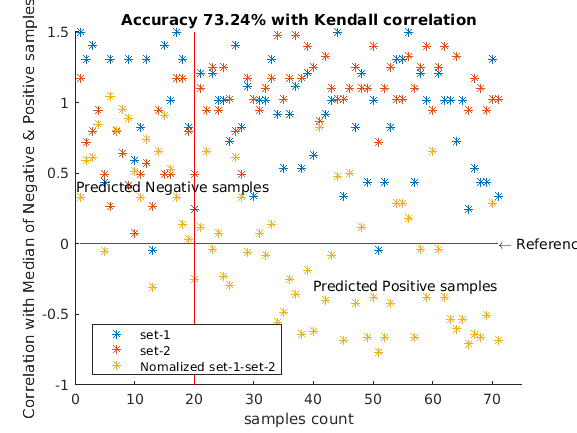

hold off
xlabel('samples count')
ylabel('Correlation with Median of Negative & Positive samples')
title('Accuracy 73.24% with Kendall correlation');

yL = get(gca,'YLim');
q = line([20 20],yL,'Color','r');
p.Annotation.LegendInformation.IconDisplayStyle = 'off';
q.Annotation.LegendInformation.IconDisplayStyle = 'off';
str = {'Predicted Negative samples'};
text(0.1,0.4,str)
str = {'Predicted Positive samples'};
text(40,-0.3,str)
text(71,0,'\leftarrow Reference line')
xlim([0.0 75.0])
ylim([-1.00 1.50])

## Clear temporary variables

clear opts